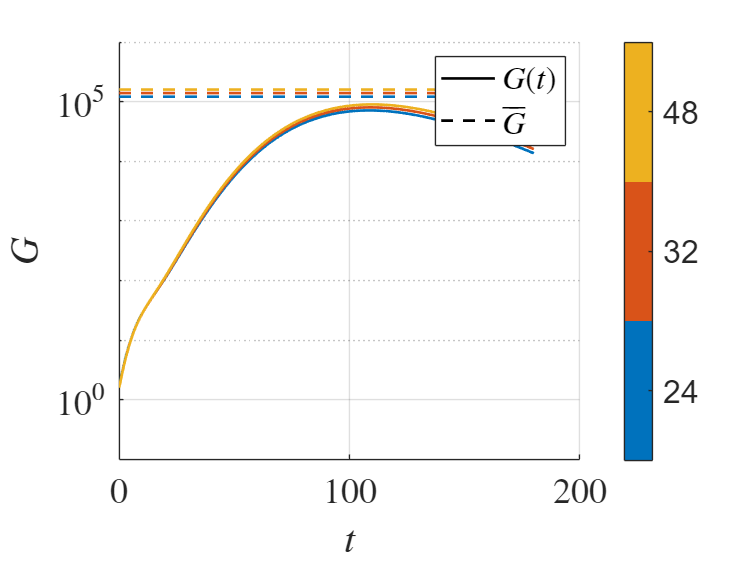

% t0 = 20;  % Single value
% T = 200;
% dt = [1, 0.5, 0.1];
% % dt = 0.5;
% % G_numeric = cell2mat(G_storage);  % Assumes all cells contain scalars
% num_M = length(dt);
% % Create figure
% figure;
% set(gca, 'YScale', 'log');
% set(groot, 'defaultTextInterpreter', 'latex');
% set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 20);
% hold on;
% 
% cmap = lines(num_M);
% set(groot, 'defaultTextInterpreter', 'latex');
% set(gca, 'TickLabelInterpreter', 'latex','FontSize',20);
% % Plot settings
% line_style = '-';   % Solid line for G_storage curves
% dash_style = '--';  % Dashed line for constant lines
% % Create dummy lines for legend
% h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5, 'DisplayName', '$G(t)$');
% h2 = plot(NaN, NaN, 'k--', 'LineWidth', 1.5, 'DisplayName', '$\overline{G}$');
% 
% for j4 = 1:length(dt)
% 
%     t_steps = round((T - t0) / dt(j4));  % Ensure integer steps
%     ttt_j = linspace(0, T - t0, t_steps);
%     % Plot constant line (dashed)
%     line([ttt_j(1), ttt_j(end)], [All_t_optimal_new(j4), All_t_optimal_new(j4)], ...
%          'Color', cmap(j4,:), ...
%          'LineStyle', dash_style, ...
%          'LineWidth', 1.5, ...
%          'HandleVisibility', 'off');
%     
%     % Plot G(t) curve (solid)
%     plot(ttt_j, G_storages_new{j4}, 'Color', cmap(j4,:), ...
%          'LineStyle', line_style, ...
%          'LineWidth', 1.5, ...
%          'HandleVisibility', 'off');
% 
% end
% 
% c = colorbar;
% colormap(cmap);
% c.Ticks = linspace(0.5/num_M, 1-0.5/num_M, num_M);
% c.TickLabels = arrayfun(@(x) num2str(x), dt, 'UniformOutput', false);
% 
% % Axis settings
% xlim([0, 200]);
% ylim([1e-1, 10^6]);
% xlabel('$t$');
% ylabel('$G$');
% grid on;
% 
% % Add legend
% legend([h1, h2], 'Interpreter', 'latex', 'Location', 'northeast','FontSize',18);
% 
% hold off;
% 


t0 = 20;  % Single value
T = 200;
dt = 1;
M = [24,32,48];
% G_numeric = cell2mat(G_storage);  % Assumes all cells contain scalars
num_M = length(M);
% Create figure
figure;
set(gca, 'YScale', 'log');
set(groot, 'defaultTextInterpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 20);
hold on;

cmap = lines(num_M);
set(groot, 'defaultTextInterpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex','FontSize',20);
% Plot settings
line_style = '-';   % Solid line for G_storage curves
dash_style = '--';  % Dashed line for constant lines
% Create dummy lines for legend
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5, 'DisplayName', '$G(t)$');
h2 = plot(NaN, NaN, 'k--', 'LineWidth', 1.5, 'DisplayName', '$\overline{G}$');

for j4 = 1:length(M)

    t_steps = round((T - t0) / dt);  % Ensure integer steps
    ttt_j = linspace(0, T - t0, t_steps);
    % Plot constant line (dashed)
    line([ttt_j(1), ttt_j(end)], [all_t_optimal_new(j4), all_t_optimal_new(j4)], ...
         'Color', cmap(j4,:), ...
         'LineStyle', dash_style, ...
         'LineWidth', 1.5, ...
         'HandleVisibility', 'off');
    
    % Plot G(t) curve (solid)
    plot(ttt_j, G_storages_new{j4}, 'Color', cmap(j4,:), ...
         'LineStyle', line_style, ...
         'LineWidth', 1.5, ...
         'HandleVisibility', 'off');

end

c = colorbar;
colormap(cmap);
c.Ticks = linspace(0.5/num_M, 1-0.5/num_M, num_M);
c.TickLabels = arrayfun(@(x) num2str(x), M, 'UniformOutput', false);

% Axis settings
xlim([0, 200]);
ylim([1e-1, 10^6]);
xlabel('$t$');
ylabel('$G$');
grid on;

% Add legend
legend([h1, h2], 'Interpreter', 'latex', 'Location', 'northeast','FontSize',18);

hold off;